clear variables; clc;

% Load the MNIST dataset
train_data = load_mnist_images('dataset/train-images.idx3-ubyte');
test_data = load_mnist_images('dataset/t10k-images.idx3-ubyte');
train_labels = load_mnist_labels('dataset/train-labels.idx1-ubyte');
test_labels = load_mnist_labels('dataset/t10k-labels.idx1-ubyte');

% Get the no. of training and testing samples
len_train = size(train_labels, 1);
len_test = size(test_labels, 1);

% Take inputs from user
use_cnn = input('Which classifier do you want to use? 0:SVM, 1:CNN ');
if use_cnn == 0
    kernel = input('Which kernel do you want to use? 0:Linear, 1:Poly, 2:RBF ');
    dr_method = input('Which dimensioanlity reduction method do you want to apply? 0:PCA, 1:LDA ');
end

% Reduce dimensionality of the training data
if use_cnn == 0
    weights = reduce_dimension(dr_method, train_data', train_labels);
    new_train_data = weights' * train_data;
    new_test_data = weights' * test_data;
end

.........*
optimization finished, #iter = 9528
nu = 0.048032
obj = -2114.505758, rho = -0.529609
nSV = 2865, nBSV = 2066
Total nSV = 2865
.........*
optimization finished, #iter = 9994
nu = 0.046739
obj = -2055.203659, rho = -0.512652
nSV = 2810, nBSV = 2001
Total nSV = 2810
........*
optimization finished, #iter = 8415
nu = 0.040011
obj = -1754.096734, rho = -0.568739
nSV = 2463, nBSV = 1697
Total nSV = 2463
........*
optimization finished, #iter = 8845
nu = 0.038494
obj = -1685.138352, rho = -0.541644
nSV = 2428, nBSV = 1620
Total nSV = 2428
........*
optimization finished, #iter = 8179
nu = 0.035077
obj = -1521.472194, rho = -0.587566
nSV = 2253, nBSV = 1471
Total nSV = 2253
...........*
optimization finished, #iter = 11453
nu = 0.041176
obj = -2277.522295, rho = -0.542591
nSV = 3054, nBSV = 2219
Total nSV = 3054
...*
optimization finished, #iter = 3398
nu = 0.038246
obj = -1692.846933, rho = -1.497875
nSV = 1933, nBSV = 1773
Total nSV = 1933
...*
optimization finished, #iter = 3005

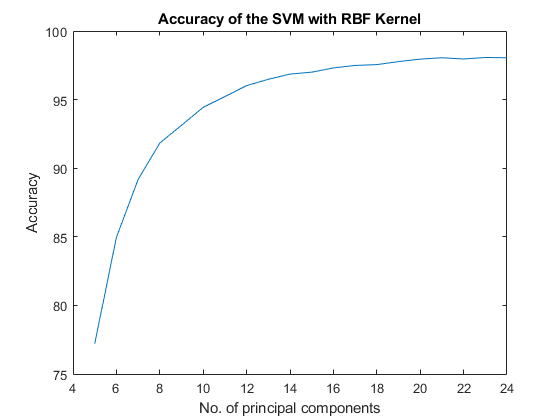

if use_cnn == 0

    % Linear SVM
    accuracy = svm(kernel, new_train_data, new_test_data, train_labels, test_labels, len_test)
elseif use_cnn == 1
    % CNN
    accuracy = CNN(train_data, test_data, train_labels, test_labels, len_train, len_test)
else
    disp('Invalid choice of classifier!');
end


.*
optimization finished, #iter = 1387
nu = 0.042502
obj = -1770.784615, rho = -10.705768
nSV = 2052, nBSV = 2029
Total nSV = 2052
.*
optimization finished, #iter = 1443
nu = 0.042285
obj = -1761.952032, rho = -10.717957
nSV = 2043, nBSV = 2017
Total nSV = 2043
.*
optimization finished, #iter = 1203
nu = 0.036987
obj = -1540.783343, rho = -10.242162
nSV = 1785, nBSV = 1765
Total nSV = 1785
.*
optimization finished, #iter = 1222
nu = 0.034939
obj = -1455.479887, rho = -9.646193
nSV = 1688, nBSV = 1667
Total nSV = 1688
.*
optimization finished, #iter = 1093
nu = 0.033114
obj = -1375.722052, rho = -9.839941
nSV = 1600, nBSV = 1582
Total nSV = 1600
.*
optimization finished, #iter = 1463
nu = 0.036798
obj = -1924.499077, rho = -10.981044
nSV = 2218, nBSV = 2199
Total nSV = 2218
.*
optimization finished, #iter = 1587
nu = 0.051587
obj = -2243.432046, rho = -9.215518
nSV = 2483, nBSV = 2470
Total nSV = 2483
.*
optimization finished, #iter = 1557
nu = 0.051077
obj = -2222.779373, rho = -8.8171

accuracy = 90.2000